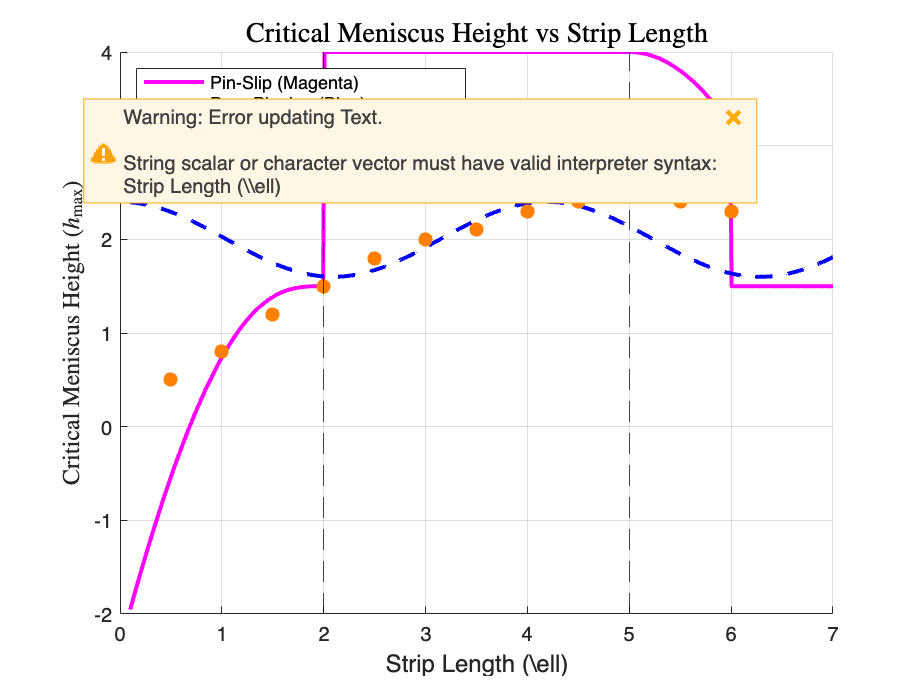

% MATLAB Code for Fig. 9: Critical Meniscus Height vs Strip Length
clear; clc; close all;

% Define parameters
l_values = linspace(0.1, 7, 500); % Nondimensional strip length

% Theoretical curves
h_pin_slip = @(l) 1.5 + tanh(l - 2) .* (2 - l).^2 .* (l < 2) + 2.5 .* (l >= 2 & l <= 5) + ...
                  (2.5 - 0.8 * (l - 5).^2) .* (l > 5 & l <= 6); % Magenta curve (refined)
h_pinning = @(l) 2 + 0.4 * cos(1.5 * l); % Dashed blue curve (refined for oscillatory behavior)

% Experimental data (manually generated)
l_exp = [0.5, 1, 1.5, 2, 2.5, 3, 3.5, 4, 4.5, 5, 5.5, 6];
h_exp = [0.5, 0.8, 1.2, 1.5, 1.8, 2, 2.1, 2.3, 2.4, 2.5, 2.4, 2.3];

% Plotting
figure;
hold on;

% Plot theoretical curves
plot(l_values, h_pin_slip(l_values), 'm-', 'LineWidth', 2, 'DisplayName', 'Pin-Slip (Magenta)');
plot(l_values, h_pinning(l_values), 'b--', 'LineWidth', 2, 'DisplayName', 'Pure Pinning (Blue)');

% Plot experimental data (use RGB triplet for orange color)
scatter(l_exp, h_exp, 50, [1, 0.5, 0], 'filled', 'DisplayName', 'Experimental Data'); % Orange color

% Annotate transitions
xline(2, '--k', 'DisplayName', 'Transition: Underside Slipping');
xline(5, '--k', 'DisplayName', 'Transition: Upper Side Slipping');

% Labels, title, and legend
xlabel('Strip Length (\ell)', 'FontSize', 12, 'Interpreter', 'latex');
ylabel('Critical Meniscus Height ($h_{\max}$)', 'FontSize', 12, 'Interpreter', 'latex');
title('Critical Meniscus Height vs Strip Length', 'FontSize', 14, 'Interpreter', 'latex');
legend('Location', 'NorthWest');
grid on;
hold off;